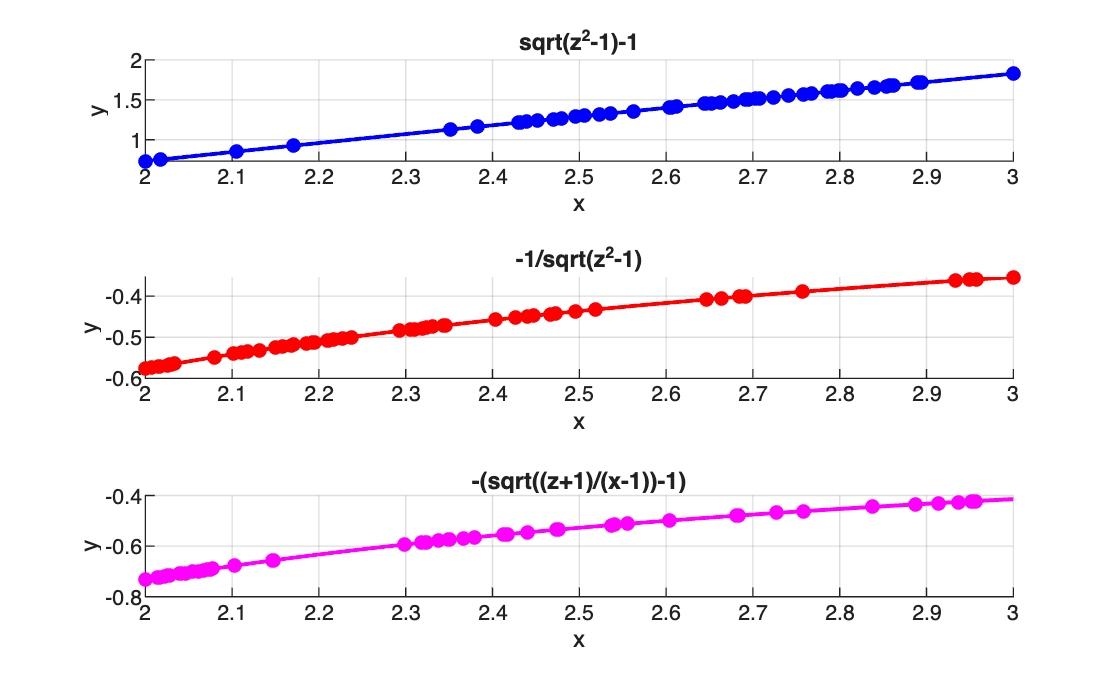

sqrt(z^2-1)-1


    50



-1/sqrt(z^2-1)


    50



-(sqrt((z+1)/(x-1))-1)


    49



close all
clear

x = linspace(2,3,1e5);
xx = linspace(2,3,1e5);

f1 = @(z) sqrt(z.^2-1)-1;
f2 = @(z) -(1./sqrt(z.^2-1));
f3 = @(z) -(sqrt((z+1)./(z-1))-1);

funcs = {f1,f2,f3};
names = {"sqrt(z^2-1)-1","-1/sqrt(z^2-1)","-(sqrt((z+1)/(x-1))-1)"};
colors = {"b","r","m"};

figure
tiledlayout(3,1)

for k = 1:3
    nexttile
    hold on

    f = funcs{k};
    y = f(x);

    [r,pol,res,zer,zj] = aaa(y,x,"mmax",50,"tol",0);

    plot(xx,f(xx),"k","LineWidth",1.2)
    plot(xx,r(xx),"Color",colors{k},"LineWidth",1.5)
    plot(zj,f(zj),"o","Color",colors{k},"MarkerFaceColor",colors{k},"MarkerSize",5)

    grid on
    xlabel("x")
    ylabel("y")
    title(names{k})
end